# Demonstration of PyColormap4Matlab

## Basic syntax

The syntax to retrieve the colormap values for a specific colormap, e.g. 'coolwarm', with 128 color quantization levels is

cmap = getPyPlot_cMap('coolwarm',128);

## Retrieve available colormap names

cmNames = getPyPlot_cMap('!GetNames');

This returns a cellstring containing all colormap names available in matplotlib.

## Visualize all colormaps

Retrieving all colormaps will take a while because the python script is called for each colormap.

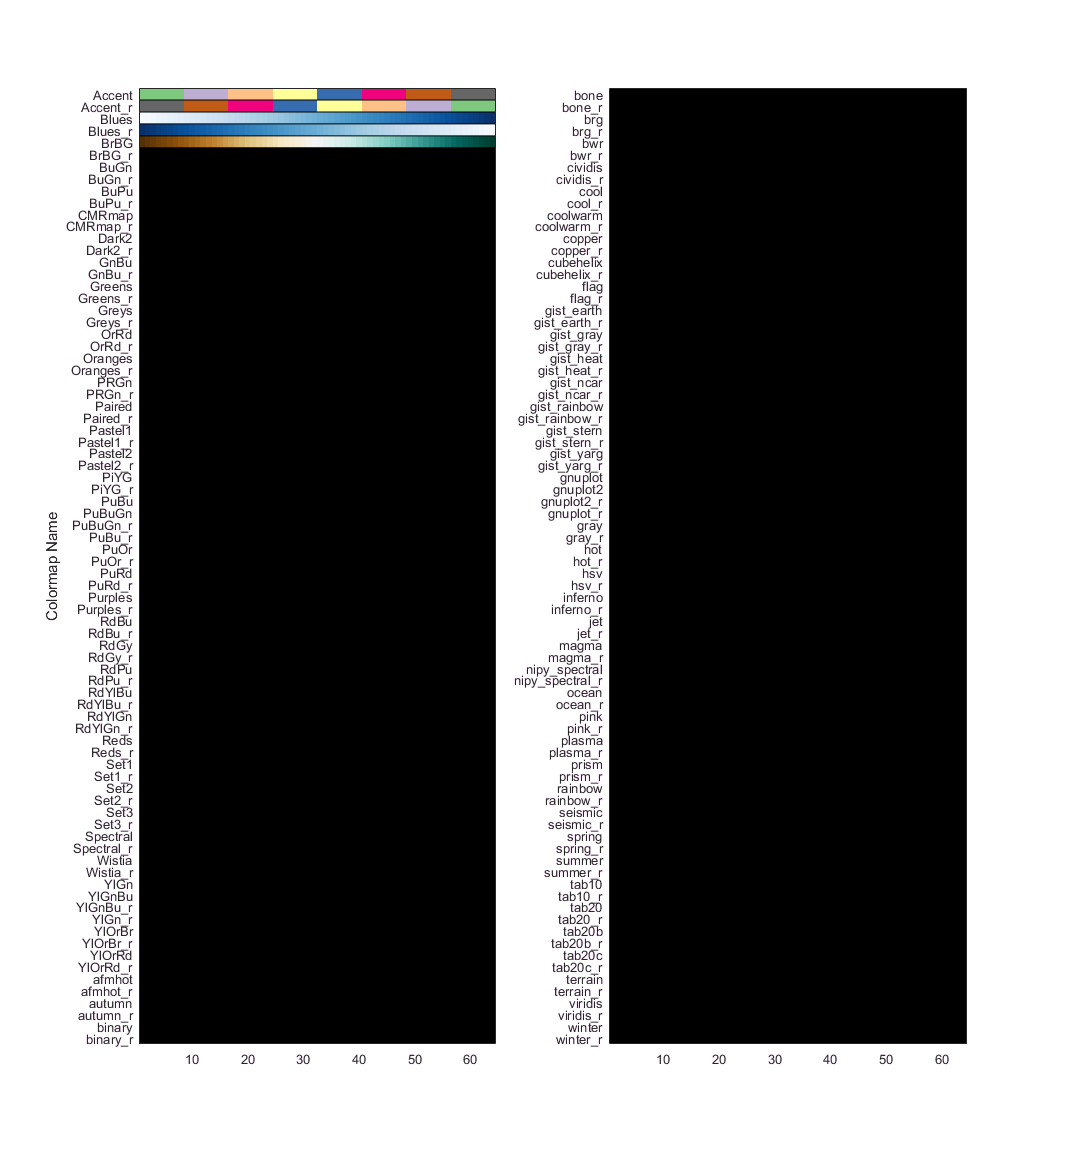

n_col = 64;
n_maps = numel(cmNames);
cmaps = zeros(n_maps,n_col,3);
for i=1:n_maps
    cmaps(i,:,:) = getPyPlot_cMap(cmNames{i},n_col);
end

nmap_split = ceil(n_maps/2);

axh(1) = subplot(1,2,1);
image(axh(1),cmaps(1:nmap_split,:,:));
line(axh(1), [0 n_col+1], repmat((1.5:nmap_split).',1,2), ...
    'Color', 'k');

axh(2) = subplot(1,2,2);
image(axh(2),cmaps(nmap_split+1:n_maps,:,:));
line(axh(2), [0 n_col+1], repmat((1.5:nmap_split).',1,2), ...
    'Color', 'k');

axh(1).Parent.Units = 'points';
axh(1).Parent.Position = [0 0 800 nmap_split*11];

set(axh(1), ...
    'FontSize',      10, ...
    'YLim',          [.5 nmap_split+.5], ...
    'YLabel',        text('String','Colormap Name'), ...
    'YTick',         1:nmap_split, ...
    'YTickLabel',    strrep(cmNames(1:nmap_split), '_', '\_'), ...
    'TickLength',    [0 0]);

set(axh(2), ...
    'FontSize',      10, ...
    'YLim',          [.5 n_maps-nmap_split+.5], ...
    'YTick',         1:n_maps-nmap_split, ...
    'YTickLabel',    strrep(cmNames(nmap_split+1:n_maps), '_', '\_'), ...
    'TickLength',    [0 0]);